# prepare_Seasonality()

## ET


ET_path = 'C:\PROJECT_FILES\INPUT_DATA\ET\ET_ANOMALY\ET_ANOMALY.mat';
dest_path = 'C:\PROJECT_FILES\INPUT_DATA\ET\ET_ANOMALY\ET_seasonal.mat';

load(ET_path);

for i=1:size(ET_ANOMALY)
    y1= MONTH_ET(i,:);
    [~,~,~,~,~,ET_Ir]=seasonality2(y1, TIME, 'Evapotranspiration', 'N');
    ET_Irr(i,:)=ET_Ir(1,:);
   
end

save(dest_path,'LAT', 'LON', 'TIME', 'ET_ANOMALY', 'MONTH_ET', 'ET_Irr');


## PPT

PPT_path = 'C:\PROJECT_FILES\INPUT_DATA\PPT\ppt_anomaly\PPT_ANOMALY.mat';
dest_path = 'C:\PROJECT_FILES\INPUT_DATA\PPT\PPT_ANOMALY\PPT_seasonal.mat';

load(PPT_path);

for i=1:size(PPT_ANOMALY)
    y2= MONTH_PPT(i,:);
    [~,~,~,~,~,PPT_Ir]=seasonality2(y2, TIME, 'Precipitation', 'N'); % The last two options are for supplying the 'title' and for choosing to 'plot' 
    PPT_Irr(i,:)=PPT_Ir(1,:);
end

save(dest_path,'LAT', 'LON', 'TIME', 'PPT_ANOMALY', 'MONTH_PPT', 'MEAN_PPT', 'PPT_Irr');

## Temperature

TEMP_path = 'C:\PROJECT_FILES\INPUT_DATA\TMEAN\TEMP_ANOMALY\TEMP_ANOMALY.mat';
dest_path = 'C:\PROJECT_FILES\INPUT_DATA\TMEAN\TEMP_ANOMALY\TEMP_seasonal.mat';

load(TEMP_path);

for i=1:size(TEMP_ANOMALY)
    y2= MONTH_TEMP(i,:);
    [~,~,~,~,~,TEMP_Ir]=seasonality2(y2, TIME, 'Temperature', 'N');
    TEMP_Irr(i,:) =  TEMP_Ir(1,:);
end

save(dest_path,'LAT', 'LON', 'TIME', 'TEMP_ANOMALY', 'MONTH_TEMP', 'TEMP_Irr');



## SOIL_MOISTURE


SOIL_path = 'C:\PROJECT_FILES\INPUT_DATA\SOIL_MOISTURE\SOIL_2002_16_corrected2.mat';
dest_path = 'C:\PROJECT_FILES\INPUT_DATA\SOIL_MOISTURE\\SOIL_seasonal.mat';

load(SOIL_path);

%Some extra data present in Soil Moisture
TIME2=datetime(TIME, 'ConvertFrom','datenum');
yr=TIME2.Year;
mon= TIME2.Month;

I= find(yr <=2002 & mon <10)

I =      1
     2
     3
     4
     5
     6
     7
     8
     9



RZSM_f(:,I)=[];
RZSM_d3(:,I)=[];
RZSM_d2(:,I)=[];
RZSM_d1(:,I)=[];
TIME(I)=[];


for i=1:size(RZSM_f)
    y2= RZSM_f(i,:);
    [~,~,~,~,~,SOIL_Ir]=seasonality2(y2, TIME, 'Soil Moisture', 'N');
    SOIL_Irr(i,:)=SOIL_Ir(1,:);
end

save(dest_path,'LAT', 'LON', 'TIME', 'RZSM_f', 'RZSM_d1', 'RZSM_d2', 'RZSM_d3', 'SOIL_Irr');


## GRACE

GRACE_path = 'C:\PROJECT_FILES\INPUT_DATA\GRACE_RESULTS\CentralValley_CSR_200204_201706.mat';
dest_path = 'C:\PROJECT_FILES\INPUT_DATA\GRACE_RESULTS\SEASONAL\GRACE_seasonal'

load(GRACE_path);
time_GRACE  = ConvertSerialYearToDate(t1); %t1 is for left out months too
time_GRACE2 = ConvertSerialYearToDate(t2);

I_GRACE  = find(time_GRACE> 731490 & time_GRACE < 736634); %Between October 2002 and October 2016
I_GRACE2 = find(time_GRACE2> 731490 & time_GRACE2 < 736634); %Between October 2002 and October 2016

time_GRACE = time_GRACE(I_GRACE);
time_GRACE2 = time_GRACE2(I_GRACE2);

% %Filter out only the months needed
% GRACE_grid_scaled = csr_grid_CentralValley_G300_Chen_scale(:,:,I_GRACE);
% GRACE_grid        = csr_grid_CentralValley_G300_Chen(:,:,I_GRACE);

%% Coordinate selection
[row, col]=find(lg_msk_CentralValley==1);
% Following variables are for creating the Grid for coordinates 
lon_grid= 0.125:0.25:359.875;
lat_grid = 89.875:-0.25:-89.875;
lon_grid=rem((lon_grid+180),360)-180;

lat_GRACE = lat_grid(row);
lon_GRACE  = lon_grid(col); 


GRACE_grid_scaled2 = csr_grid_CentralValley_G300_Chen_scale_interp(:,:,I_GRACE2);
GRACE_grid2        = csr_grid_CentralValley_G300_Chen_interp(:,:,I_GRACE2);

[A, I_interp]=setdiff(time_GRACE2,time_GRACE); %The months which have been interpolated (to be re,oved later from the seasonal components)

for i=1:size(csr_grid_CentralValley_G300_Chen_scale_interp,3)
    GRACE_grid_scaled_t= GRACE_grid_scaled2(:,:,i);
    GRACE_vec_scaled(:,i) = GRACE_grid_scaled_t(I);
    GRACE_grid_t= GRACE_grid2(:,:,i);
    GRACE_vec(:,i) = GRACE_grid_t(I);  
end

for i=1:size(GRACE_vec)
    y5= GRACE_vec_scaled(i,:);
    [~,~,~,~,~,GRACE_Ir]=seasonality2(y5, time_GRACE2, 'GRACE');
    GRACE_Irr(i,:)=GRACE_Ir(1,:);
end

GRACE_Irr(I_interp) = []; %Just need the months which are not interpolated

save(dest_path, 'lat_GRACE', 'lon_GRACE', 'GRACE_vec_scaled', 'GRACE_vec', 'GRACE_Irr');





## Trends

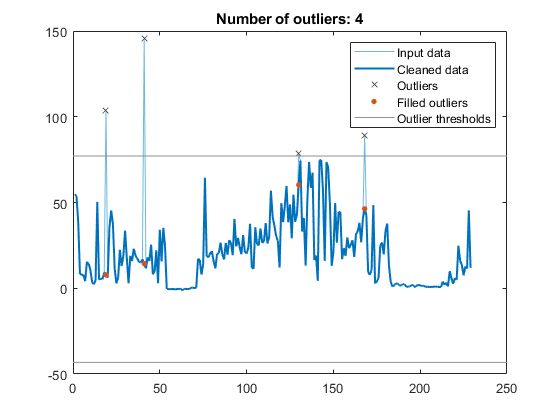

% Fill outliers
[cleanedData,outlierIndices,thresholdLow,thresholdHigh] = filloutliers(GW,...
    'makima');

% Visualize results
clf
plot(GW,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(cleanedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(find(outlierIndices),GW(outlierIndices),'x','Color',[64 64 64]/255,...
    'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices))])

% Plot filled outliers
plot(find(outlierIndices),cleanedData(outlierIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices thresholdLow thresholdHigh